## 6.2.3.1. Специальные исследования акустических и виброакустических каналов

Третьеоктавные фильтры с центральными частотами

clear
fc=[315 400 500 630 800 1000 1250 1600 2000 2500 ...
    3150 4000 5000 6300 8000]

fc =          315         400         500         630         800        1000        1250        1600        2000        2500        3150        4000        5000        6300        8000


syms fv(i) fn(i)

Для каждой i-ой частотной полосы на каждой среднегеометрической частоте

fsr(i)=sqrt(fv(i)*fn(i))

$$fsr(i) = \sqrt{\mathrm{fn}\left(i\right)\,\mathrm{fv}\left(i\right)}$$

определяется формантный параметр $\Delta A_i$ характеризующий энергетическую избыточность дискретной составляющей речевого сигнала:

syms Ici Ai f
DAi=Ici-Ai    % дБ    (6.1)

$$DAi = \mathrm{Ici}-\mathrm{Ai}$$

% где 
% L_s(i) - средний спектральный уровень речевого сигнала
% в контрольной точек для i-й спектральной полосы;
% A(i) - средний спектральный модальный уровень 
% формант в той же полосе.

DAf(f)=piecewise(f<=1000,200/f^(0.43)-0.37,f>1000,1.37+1000/f^0.69)   % (6.2)

$$DAf(f) = \left\{ \begin{array}{cl} \frac{200}{f^{43/100}}-\frac{37}{100} & \text{ if }f\leq 1000\\ \frac{1000}{f^{69/100}}+\frac{137}{100} & \text{ if }1000<f \end{array}\right.$$

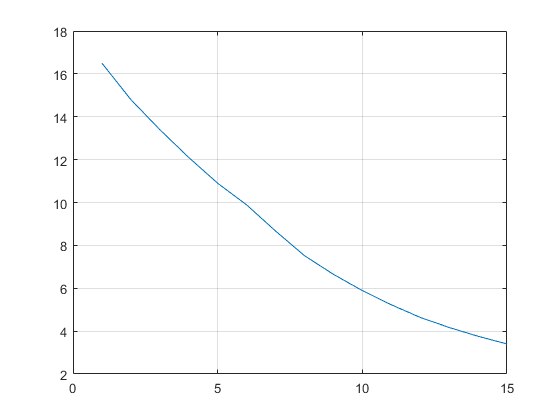

% где DAf(fsri)=DAi(i)
n=15;
digits(3)
for i=1:n
    DAi(i)=vpa(DAf(fc(i)));
end
plot([1:15],DAi)
grid on